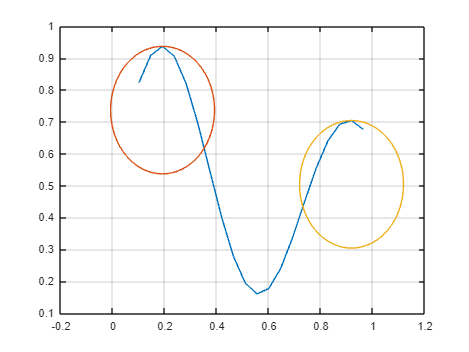



close all
clear all
clc

x = 0.1:1/22:1;
% norima funkcija
yTarget = ((1 + 0.6*sin(2*pi*x/0.7)) + 0.3*sin(2*pi*x))/2;
[peaks, locs] = findpeaks(yTarget, x);


w0 = randn(1);
w1 = randn(1);
w2 = randn(1);

% centrų ir spindulių reikšmės
c1 = locs(1,1);
c2 = locs(1,2);
r1 = 0.20;
r2 = 0.20;

% --------Pradiniu duomenu grafikas
figure(1);
plot(x, yTarget);
hold on;

% Apskritimas nr. 1
theta = linspace(0, 2*pi, 100); % nuo 0 iki 2*pi (pilnas apskritimas)
xR1 = c1 + r1 * cos(theta);
yR1 = (peaks(1) - r1) +  r1* sin(theta);
plot(xR1, yR1)

% Apskritimas nr. 2
xR2 = c2 + r2 * cos(theta);
yR2 = (peaks(2) - r2) +  r2* sin(theta);
plot(xR2, yR2)
grid on
hold off

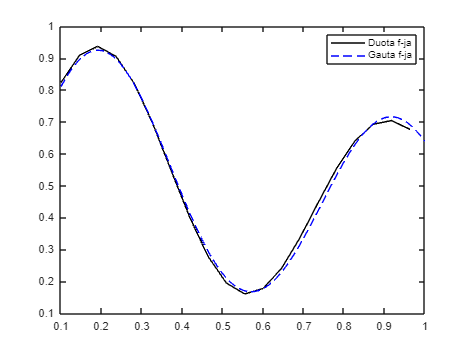

% ---------------------------------------------

% mokymo zingsnis
step = 0.1;
% -----------Mokymas-----------------------
for k=1:2000
    for n=1:20
      F1=exp(-((x(n)-c1)^2)/(2*(r1^2)));
      F2=exp(-((x(n)-c2)^2)/(2*(r2^2)));

      yFunction(n) = F1*w1+F2*w2+w0;
      % nuokrypis nuo norimos funkcijos
      delta = yTarget(n)-yFunction(n);

      w1 = w1 + step * delta * F1;
      w2 = w2 + step * delta * F2;
      w0 = w0 + step * delta;
    end
end
% ---------------------------------------------

%---------TESTAVIMAS---------------------------
x_test = linspace(0.1, 1, 200);
yTarget_Test = ((1 + 0.6*sin(2*pi*x_test/0.7)) + 0.3*sin(2*pi*x_test))/2;
for m = 1:200
    F1=exp(-((x_test(m)-c1)^2)/(2*(r1^2)));
    F2=exp(-((x_test(m)-c2)^2)/(2*(r2^2)));
    y_test(m) = F1*w1+F2*w2+w0;
    Offset(m) = y_test(m) - yTarget_Test(m);
end

figure(2)
plot(x, yTarget,"k", x_test,y_test, "b--")
legend('Duota f-ja', 'Gauta f-ja')

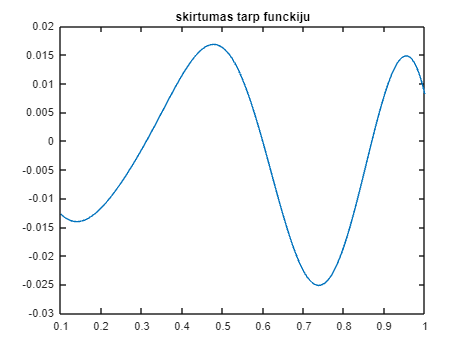


figure(3)
plot(x_test, Offset)
title('skirtumas tarp funckiju');